# Question 1

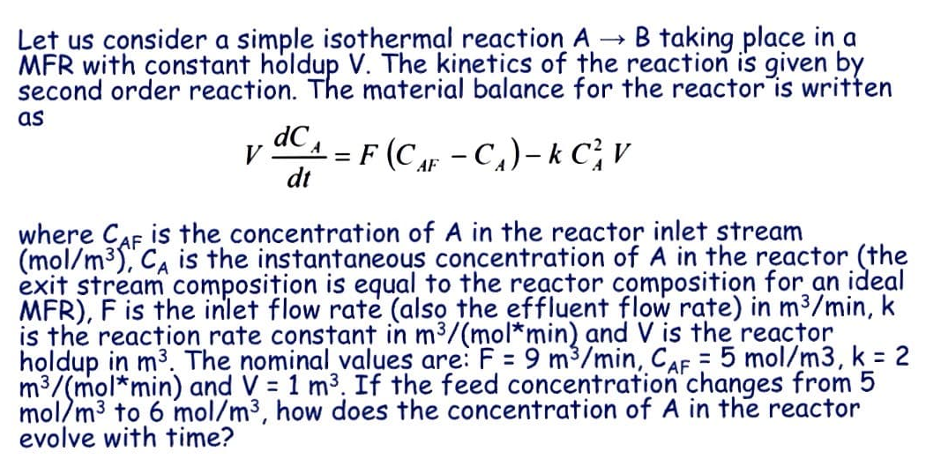

clear;clc;
V=1;F=9;Caf=5;k=2;
% Ca can be found using quadratic
b=F/(k*V);c=(-F*Caf)/(k*V);a=1;
Cas=(-b+sqrt(b^2-4*a*c))/(2*a) %Ca at steady state=3

Cas = 3

## Solving

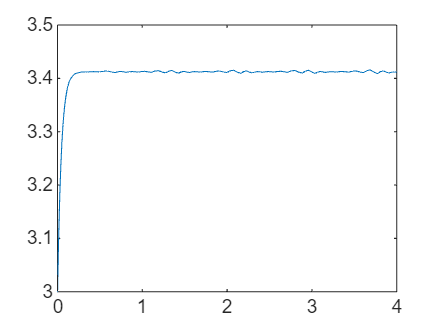

Caf_New=6;
[t1,y]=ode45(@(t,Ca)g(t,Ca,F,V,Caf_New,k),[0,4],Cas);
plot(t1,y);

function dydt=g(~,Ca,F,V,Caf,k)
    dydt=F/V*(Caf-Ca)-k*Ca.^2;
end

## Part 2 & 3

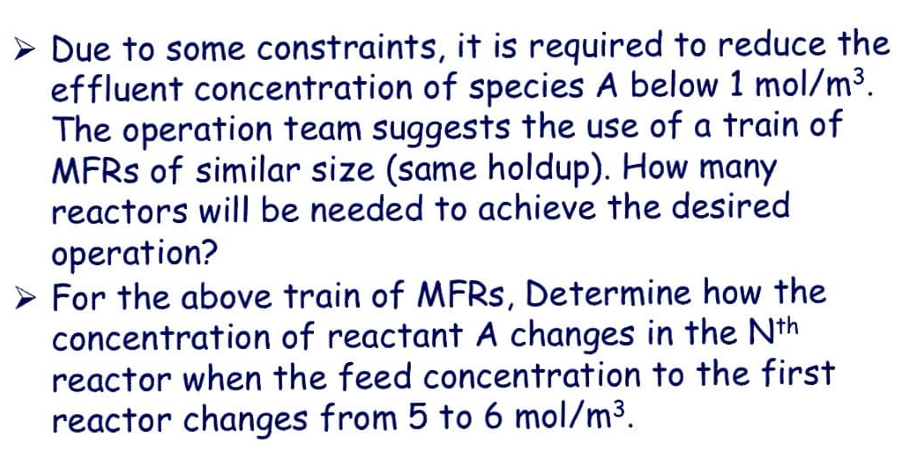

%ca_in=5;
ca_in=5;
b=F/(k*V);
a=1;
counter=0;
while abs(ca_in)>1
    c=(-F*ca_in)/(k*V);
    ca_out=(-b+sqrt(b^2-4*a*c))/(2*a);
    ca_in=ca_out;
    disp(ca_out);
    counter=counter+1;
end

     3

    2.0584

    1.5349

    1.2097

    0.9913




disp("Number of MFRs Required="+counter)

Number of MFRs Required=5


## Part 3

# Question 2

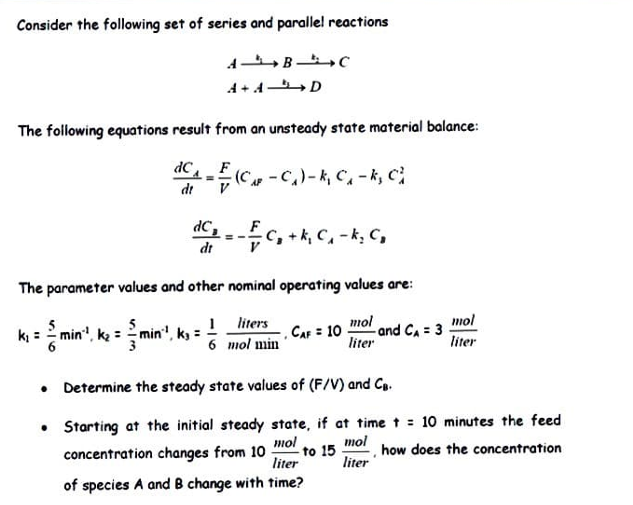

## Part 1

clear;clc;
clearpoints
% Givens
k1=5/6;k2=5/3;k3=1/6;Caf=10;Ca=3;

% At steady state: d(Ci)/dt=0
FbyV_s=(k3*Ca^2+k1*Ca)/(Caf-Ca);
Cb=(k1*Ca)/(k2+FbyV_s);
disp("F/V is"+FbyV_s);

F/V is0.57143


disp("Cb is "+Cb)

Cb is 1.117


## Part 2

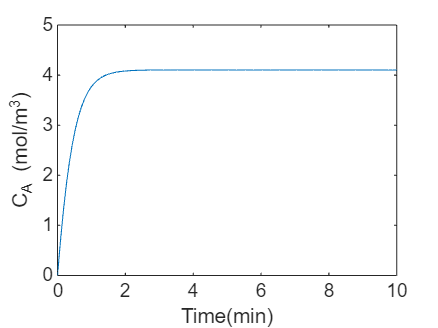

Caf_2=15;
[t1,ca]=ode45(@(t,ca)f(t,ca,FbyV_s,Caf_2,k1,k2,k3),[0,10],0);
plot(t1,ca);
xlabel("Time(min)")
ylabel("C_A (mol/m^3)")

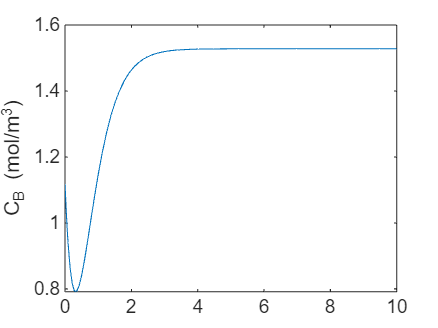

function dcadt=f(t,Ca,FbyV,Caf,k1,k2,k3)
    dcadt=FbyV*(Caf-Ca(1))-k1*Ca(1)-k3*Ca(1)^2;
    %dcadt(2)=-FbyV*Ca(2)-k2*Ca(2)+k1*Ca(1);
end
[t2,cb]=ode45(@(t,cb)fun(t,cb,FbyV_s,ca,k1,k2,t1),[0,10],Cb);
plot(t2,cb)
%xlabel("Time(min)")
ylabel("C_B (mol/m^3)")

function dbadt=fun(t,Cb,FbyV,Ca,k1,k2,t1)
   Ca_t=interp1(t1,Ca,t);
   dbadt=-FbyV*Cb-k2*Cb+k1*Ca_t;
end

## Springgg

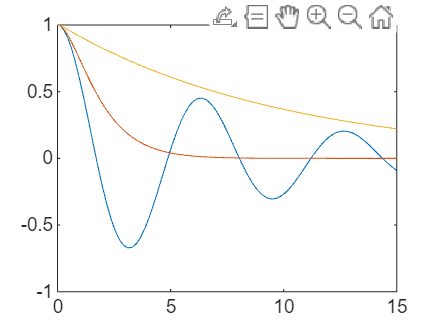

clear;clc;
c1=5;c2=40;c3=200;
[t1,x1]=ode45(@(t,y)odefcn(t,y,c1),[0,15],[1,0]);
[t2,x2]=ode45(@(t,y)odefcn(t,y,c2),[0,15],[1,0]);
[t3,x3]=ode45(@(t,y)odefcn(t,y,c3),[0,15],[1,0]);
plot(t1,x1(:,1));hold on;
plot(t2,x2(:,1));hold on;
plot(t3,x3(:,1));hold off;

function dydt=odefcn(~,y,c)
    m=20;
    k=20;
    dydt=zeros(2,1);
    dydt(1)=y(2);
    dydt(2)=(-k*y(1)-c.*y(2))./m;
end